## generate dummy data

rng(2021,'twister')

state_changes=[0;cumsum(rand(10,1)*10)];
states=[state_changes(1:end-1),state_changes(2:end),mod(cumsum(randi(2,10,1)),3)+1];
state_names={'wake','nrem','rem'};

t=0:1:state_changes(end);
fr_mean=zeros(5,length(t));
fr_ste=zeros(5,length(t));
for n=1:5
    fr_mean(n,:)=(1+rand(size(t)))*10^(n-3);
    fr_ste(n,:)=(rand(size(t)))*10^(n-3);
end

## plot data

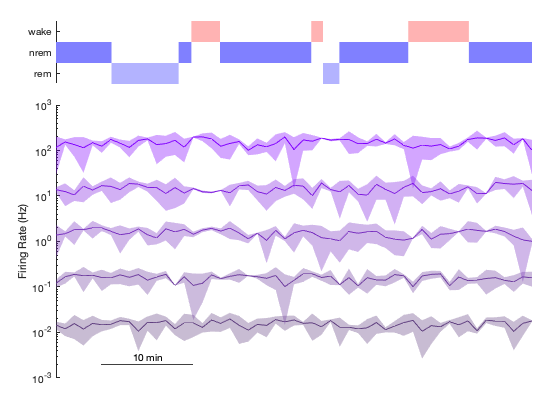

color_state=[1.0, 0.7, 0.7
       0.5, 0.5, 1.0
       0.7, 0.7, 1.0];
   
color_quintile=hsv2rgb([0.75*ones(1,5);linspace(0.5,1,5);linspace(0.5,1,5)]');
   
% hypnogram
subplot('position',[0.1,0.8,0.85,0.15])   
for s_idx=1:size(states,1)
    rectangle('Position',[states(s_idx,1),states(s_idx,3)-0.5,diff(states(s_idx,1:2)),1],...
                'LineStyle','none','facecolor',color_state(states(s_idx,3),:))
end
ax=gca;
ax.YTick=1:length(state_names);
ax.YTickLabel=state_names;
ax.YDir='reverse';
ax.XLim=t([1,end]);
ax.YLim=0.5+[0,length(state_names)];
ax.XAxis.Visible = 'off';

% firing rates
subplot('position',[0.1,0.1,0.85,0.65])   
hold on
for n=1:size(fr_mean,1)
    fill([t,fliplr(t)],[fr_mean(n,:)+fr_ste(n,:),fliplr(fr_mean(n,:)-fr_ste(n,:))],...
        color_quintile(n,:),'LineStyle','none','FaceAlpha',0.35)
    plot(t,fr_mean(n,:),'color',color_quintile(n,:))
end

t_pos_x=5+[0,10];
t_pos_y=2e-3;
plot(t_pos_x,t_pos_y*[1,1],'k-')
text(mean(t_pos_x),t_pos_y,sprintf('%d min',diff(t_pos_x)),...
    'HorizontalAlignment','center','VerticalAlignment','bottom')

ax=gca;
ax.YScale='log';
ax.XLim=t([1,end]);
ax.XAxis.Visible = 'off';
ax.YLabel.String='Firing Rate (Hz)';